# Obstruction Removal approach.

### 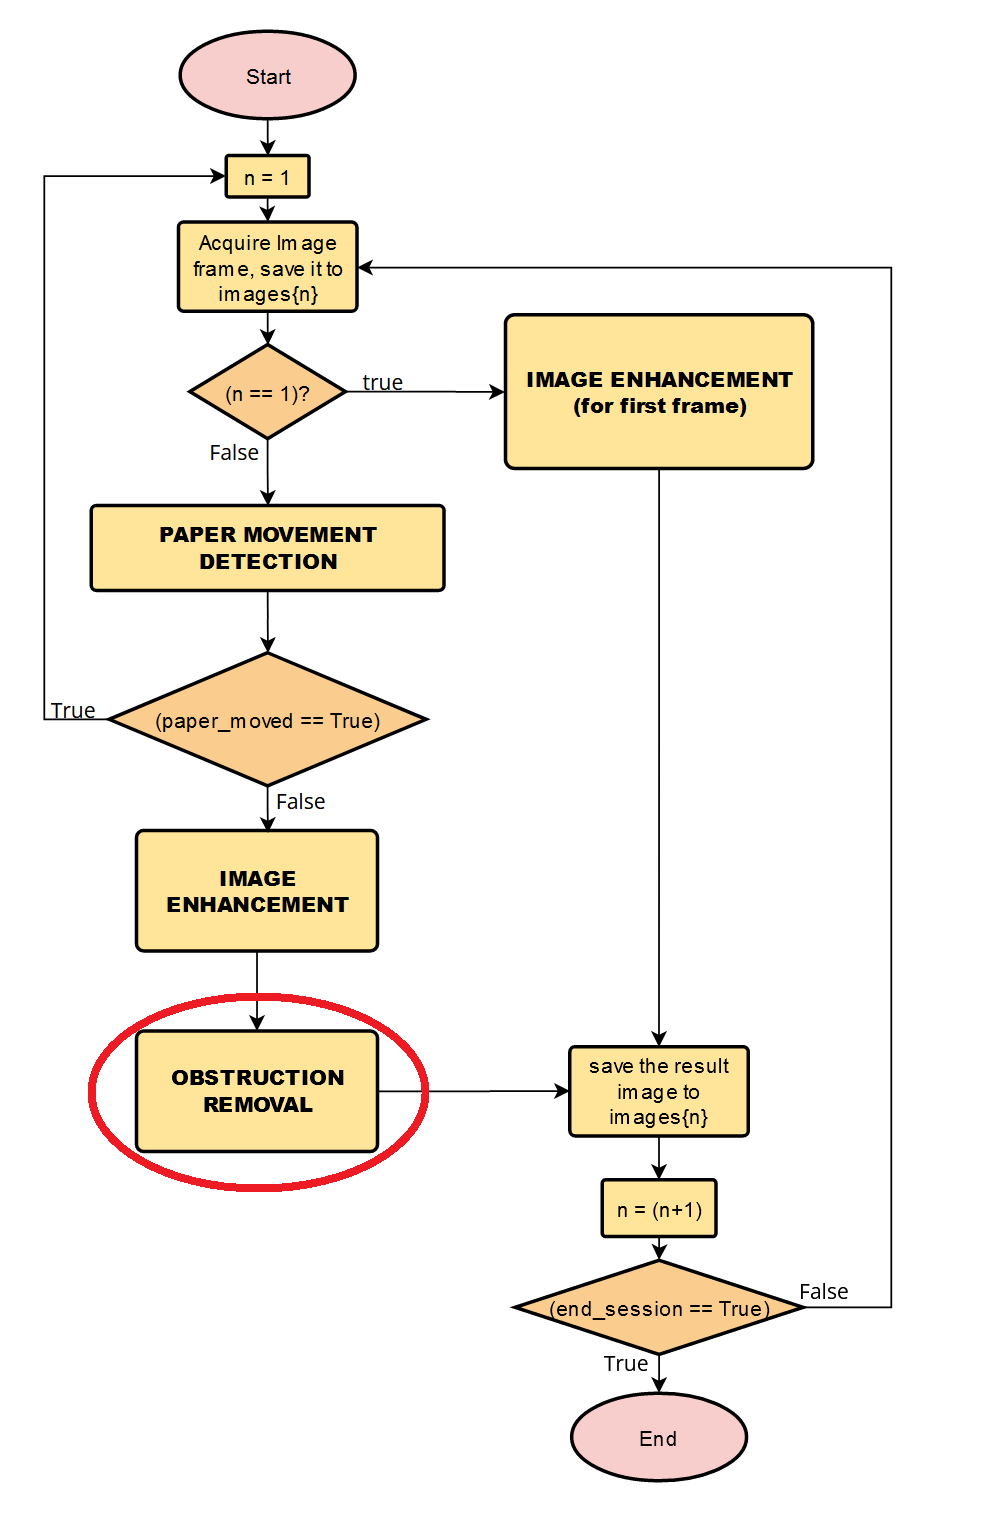

## METHODOLOGY ILLUSTRATION

The flowchart below shows basic information on the Obstruction removal algorithm that we are going to explain here below: 

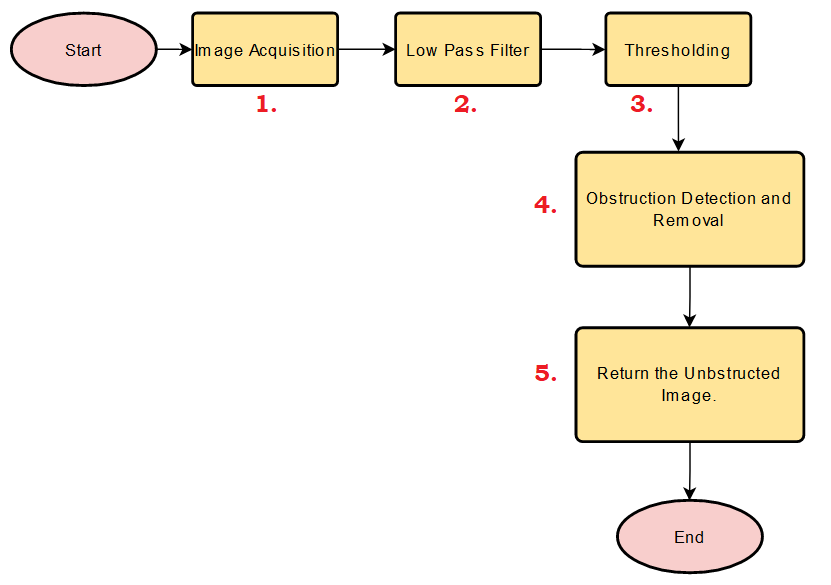

## STEP 1: IMAGE ACQUISITION

At this step, the program will read the input image and trim it so as to get at maximum the part that shows the white paper. 

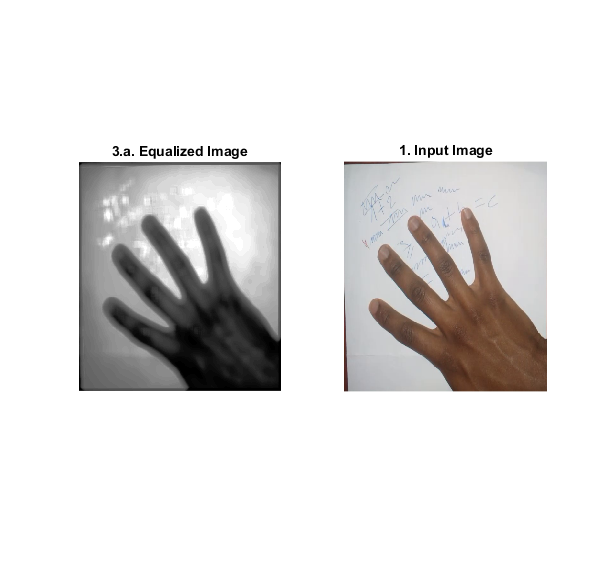

inputIm=imread("theImageWithHand.png");
% inputIm=imread("theImage.png");
[inputIm rowCr1 rowCr2 colCr1 colCr2]=whitePaperTrimmer(inputIm,0.5);
imshow(inputIm);
title("1. Input Image")

clear Mask_RGB


## STEP 2: LOW PASS FILTERING

This process will use a low pass filter to filter out any object that appears in the image, except only the obstruction (the hand). This process will use the binary mask from the image enhancement process so as to highlight penstrokes, and make sure that they do not contribute to the obstruction pixels by setting them to the highest intensity value, 255. Then the resulting image will be filtered by smoothing.

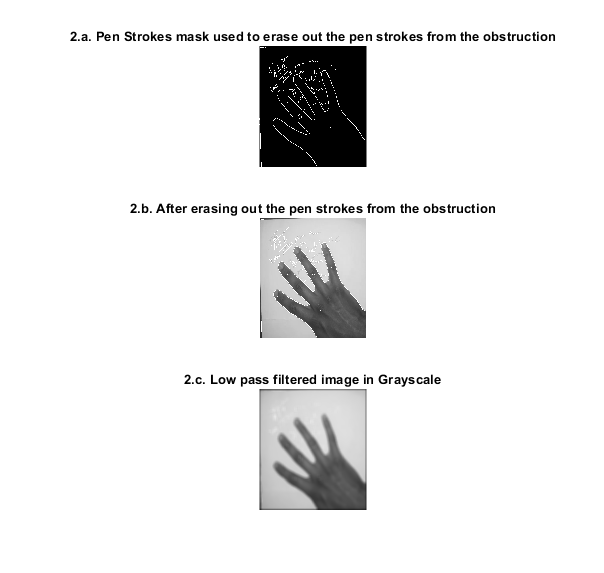

total_numberOfRows=rowCr2 - rowCr1 + 1;
total_numberOfColumns = colCr2 - colCr1 + 1;
theRowPeriod = ceil((3/100) * total_numberOfRows);
theColPeriod = ceil((3/100) * total_numberOfColumns);
LP_filter_Hand = (1/(theColPeriod*theRowPeriod)) * ones(theRowPeriod,theColPeriod);

global mypenstroke_mask
subplot(3,1,1)
imshow(mypenstroke_mask);
title("2.a. Pen Strokes mask used to erase out the pen strokes from the obstruction")
inputIm_Smoothed=rgb2gray(inputIm);
inputIm_Smoothed(mypenstroke_mask)= uint8(255);
subplot(3,1,2)
imshow(inputIm_Smoothed);
title("2.b. After erasing out the pen strokes from the obstruction")
inputIm_Smoothed = imfilter(inputIm_Smoothed,LP_filter_Hand);
subplot(3,1,3)
imshow(inputIm_Smoothed);
title("2.c. Low pass filtered image in Grayscale")

### STEP 3: THRESHOLDING

This process will threshold the smoothed outpout image from step 2. It will achieve it by first equalizing the image, then threshold it to make sure that the obstruction will be represented by 0 intensity pixels.

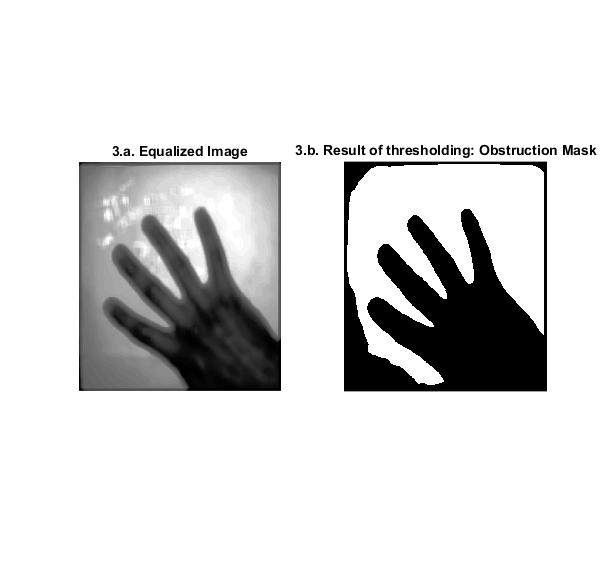

inputIm_Smoothed_eq=histeq(inputIm_Smoothed);
subplot(1,2,1)
imshow(inputIm_Smoothed_eq)

title("3.a. Equalized Image")
inputIm_Smoothed_eq_gray = (inputIm_Smoothed_eq);
inputIm_MaskOfObstruction_Binary = imbinarize(inputIm_Smoothed_eq_gray,0.5);
subplot(1,2,2)
imshow(inputIm_MaskOfObstruction_Binary)
title("3.b. Result of thresholding: Obstruction Mask")

### STEP 4: OBSTRUCTION REMOVAL

This process will replicate the created obstruction mask into three dimensions so as to multiply (element-wise multiplication) with the input image, thus remove the obstruction by setting the obstruction to zero intensity. The zero intensities will be compansated by previous frame through addition.

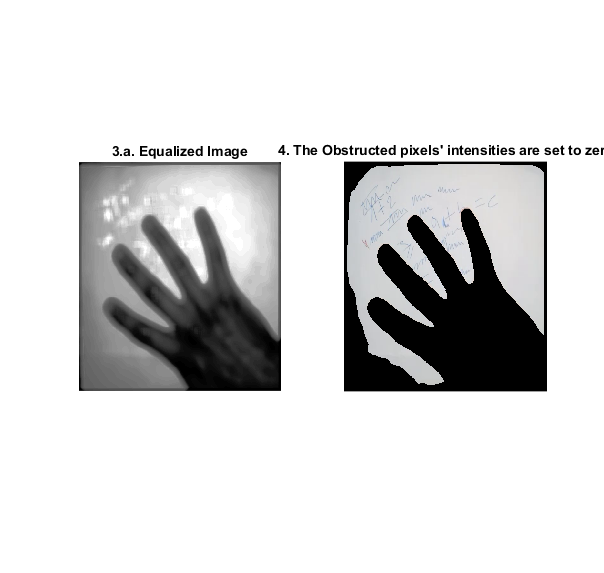


inputIm_MaskOfObstruction_Binary=uint8(inputIm_MaskOfObstruction_Binary);
Mask_RGB(:,:,1)=inputIm_MaskOfObstruction_Binary;
Mask_RGB(:,:,2)=inputIm_MaskOfObstruction_Binary;
Mask_RGB(:,:,3)=inputIm_MaskOfObstruction_Binary;


outputIm=inputIm.*(Mask_RGB);
imshow(outputIm)
title("4. The Obstructed pixels' intensities are set to zero")

It can be seen that the illumination correction is a challenge that we have to deal with, in order to have a correct obstruction mask.

### STEP 5: RETURN THE OUTPUT IMAGE

This step will return the output image to the main program.

clc